close all
clf 
clear

Env.MPH.PATH    = 'D:\wj\Back Up\0 -Doctoral research\M - MATLAB - SPPALs\';
Env.FIG.UNIT    = 'inches';
Env.FIG.WIDTH   = 3.25;
Env.FIG.HEIGHT  = 2.5;

Study.FREQ_START    = 60e3;
Study.FREQ_STOP     = 90e3;
Study.FREQ_STEP_SOLID ...
                    = 10;
Study.FREQ_STEP_ACO ...
                    = 100;
Study.freqSolid     = Study.FREQ_START:Study.FREQ_STEP_SOLID:Study.FREQ_STOP;
Study.freqAcoustic  = Study.FREQ_START:Study.FREQ_STEP_ACO:Study.FREQ_STOP;
Study.freqAcousticSecDiff = [500, 630, 800, 1e3, 1.25e3, 1.6e3, 2e3, 2.5e3, 3.15e3, 4e3, 5e3, 6.3e3, 8e3, 1e4, 1.25e4, 1.6e4, 2e4];

Study.Z_START       = 0.1;
Study.Z_STOP        = 2;
Study.Z_STOP_ACO_SEC= 1;
Study.N_Z           = 1000;

Study.TH_START      = -90/180*pi;
Study.TH_STOP       = 90/180*pi;
Study.N_TH          = 361;

%%
Air.c = 343;
Air.rho = 1.21;
%%

Plate.FREQ = 76140;
Plate.RADIUS = 50e-3;
Plate.THICKNESS = 1e-3;

Plate.tStep = Air.c/Plate.FREQ/2; %%

% Xdcr.l5 = [10.5e-3:0.25e-3:11.25e-3 43.25e-3:0.25e-3:44e-3]; % for r0=9.0 of e7
Xdcr.l5 = [10.75e-3:0.25e-3:11.5e-3 44e-3:0.25e-3:44.75e-3]; % for r0=7.0 of e7
% Xdcr.l5 = [10.25e-3:0.25e-3:10.75e-3 42.75e-3:0.25e-3:43.5e-3]; % for r0=9.0 of e5
% Xdcr.l5 = [10.5e-3:0.25e-3:11e-3 43.25e-3:0.25e-3:43.75e-3]; % for r0=7.0 of e5

Study.nXdcr = length(Xdcr.l5);

for iXdcr = 1:Study.nXdcr 
% for iXdcr = 4:4
    tic
    % tempFilename = ['optimizeSteppedPlateHighPowerTransducer_r=33.3_t=1.0_m=6_f=75_r0=9.0_l5=' num2str(Xdcr.l5(iXdcr)*1e3,'%2.2f') '.mph'];  % for r0=9.0 of e7
    tempFilename = ['optimizeSteppedPlateHighPowerTransducer_r=33.3_t=1.0_m=6_f=75_r0=7.0_l5=' num2str(Xdcr.l5(iXdcr)*1e3,'%2.2f') '.mph']; % for r0=7.0 of e7
    % tempFilename = ['optimizeSteppedPlateTransducer_r=33.3_t=1.0_m=6_f=75_r0=9.0_l5=' num2str(Xdcr.l5(iXdcr)*1e3,'%2.2f') '.mph'];  % for r0=9.0 of e5
    % tempFilename = ['optimizeSteppedPlateTransducer_r=33.3_t=1.0_m=6_f=75_r0=7.0_l5=' num2str(Xdcr.l5(iXdcr)*1e3,'%2.2f') '.mph'];  % for r0=7.0 of e5

    if exist(tempFilename,'file') == 2
        modelOptimizedSteppedPlateHighPowerTransducer = mphload(tempFilename);
    elseif exist ('modelOptimizedSteppedPlateHighPowerTransducer','var') ~= 1
        % modelOptimizedSteppedPlateHighPowerTransducer = mphload('optimizeSteppedPlateHighPowerTransducer_r=33.3_t=1.0_m=6_f=75_r0=7.0.mph'); % for r0=7.0 of e7
        modelOptimizedSteppedPlateHighPowerTransducer = mphload('optimizeSteppedPlateHighPowerTransducer_r=33.3_t=1.0_m=6_f=75_r0=9.0.mph'); % for r0=9.0 of e7
        % modelOptimizedSteppedPlateHighPowerTransducer = mphload('optimizeSteppedPlateTransducer_r=33.3_t=1.0_m=6_f=75_r0=7.0.mph'); % for r0=7.0 of e5
        % modelOptimizedSteppedPlateHighPowerTransducer = mphload('optimizeSteppedPlateTransducer_r=33.3_t=1.0_m=6_f=75_r0=9.0.mph'); % for r0=9.0 of e5
        modelOptimizedSteppedPlateHighPowerTransducer.hist.disable;

        modelOptimizedSteppedPlateHighPowerTransducer.param.set('Study_freqStart',   [num2str(Study.FREQ_START)         ' [Hz]']);
        modelOptimizedSteppedPlateHighPowerTransducer.param.set('Study_freqStep',    [num2str(Study.FREQ_STEP_SOLID)    ' [Hz]']);
        modelOptimizedSteppedPlateHighPowerTransducer.param.set('Study_freqStop',    [num2str(Study.FREQ_STOP)          ' [Hz]']);

        % modelOptimizedSteppedPlateHighPowerTransducer.param.set('Xdcr_l5',          [num2str(Xdcr.l5(iXdcr))            '[m]']);
        modelOptimizedSteppedPlateHighPowerTransducer.param.set('Xdcr_l3',          [num2str(Xdcr.l5(iXdcr))            '[m]']);

        mphgeom(modelOptimizedSteppedPlateHighPowerTransducer)
        mphrun(modelOptimizedSteppedPlateHighPowerTransducer,'std1')

        % tempXdcrl6 = mphglobal(modelOptimizedSteppedPlateHighPowerTransducer, 'Xdcr_l6', 'dataset', 'dset1');
        % modelOptimizedSteppedPlateHighPowerTransducer.param.set('Xdcr_l6',          [num2str(tempXdcrl6(1))            '[m]']);
        tempXdcrl6 = mphglobal(modelOptimizedSteppedPlateHighPowerTransducer, 'Xdcr_l4', 'dataset', 'dset1');
        modelOptimizedSteppedPlateHighPowerTransducer.param.set('Xdcr_l4',          [num2str(tempXdcrl6(1))            '[m]']);

        mphgeom(modelOptimizedSteppedPlateHighPowerTransducer)
        mphrun(modelOptimizedSteppedPlateHighPowerTransducer,'std2')
        
        mphsave(modelOptimizedSteppedPlateHighPowerTransducer,[Env.MPH.PATH tempFilename])
    end
    % tempXdcrl6 = mphglobal(modelOptimizedSteppedPlateHighPowerTransducer, 'Xdcr_l6', 'dataset', 'dset1');
    tempXdcrl6 = mphglobal(modelOptimizedSteppedPlateHighPowerTransducer, 'Xdcr_l4', 'dataset', 'dset1');
    Xdcr.l6(iXdcr) = tempXdcrl6(1);

    Xdcr.uSteppedPlateHighPowerTransducer(:,iXdcr) = ...
        mphevalpoint(modelOptimizedSteppedPlateHighPowerTransducer, 'solid.u_tZ', 'dataset', 'dset3','selection','box1');  
    clear modelOptimizedSteppedPlateHighPowerTransducer
    toc
end

Elapsed time is 7.664159 seconds.
Elapsed time is 6.929645 seconds.
Elapsed time is 6.955684 seconds.
Elapsed time is 7.081064 seconds.
Elapsed time is 5.839029 seconds.
Elapsed time is 6.107646 seconds.
Elapsed time is 11.662712 seconds.
Elapsed time is 6.451975 seconds.


for iXdcr = 1:Study.nXdcr
% Find the indices of the fisrt and second peaks
    [tempPks,tempLocs] = findpeaks(abs(Xdcr.uSteppedPlateHighPowerTransducer(:,iXdcr)));
    [~,tempI] = sort(tempPks,'descend');
    tempI = tempLocs(tempI);
    Xdcr.iPeak(iXdcr,:) = tempI(1:2);
% Find the index of the dip btw. the above
    tempMax = max(Xdcr.iPeak(iXdcr,:));
    tempMin = min(Xdcr.iPeak(iXdcr,:));
    tempI = islocalmin(abs(Xdcr.uSteppedPlateHighPowerTransducer(:,iXdcr)));
    tempI = find(tempI);
    Xdcr.iDip(iXdcr) = tempI(tempI > tempMin & tempI < tempMax);
end

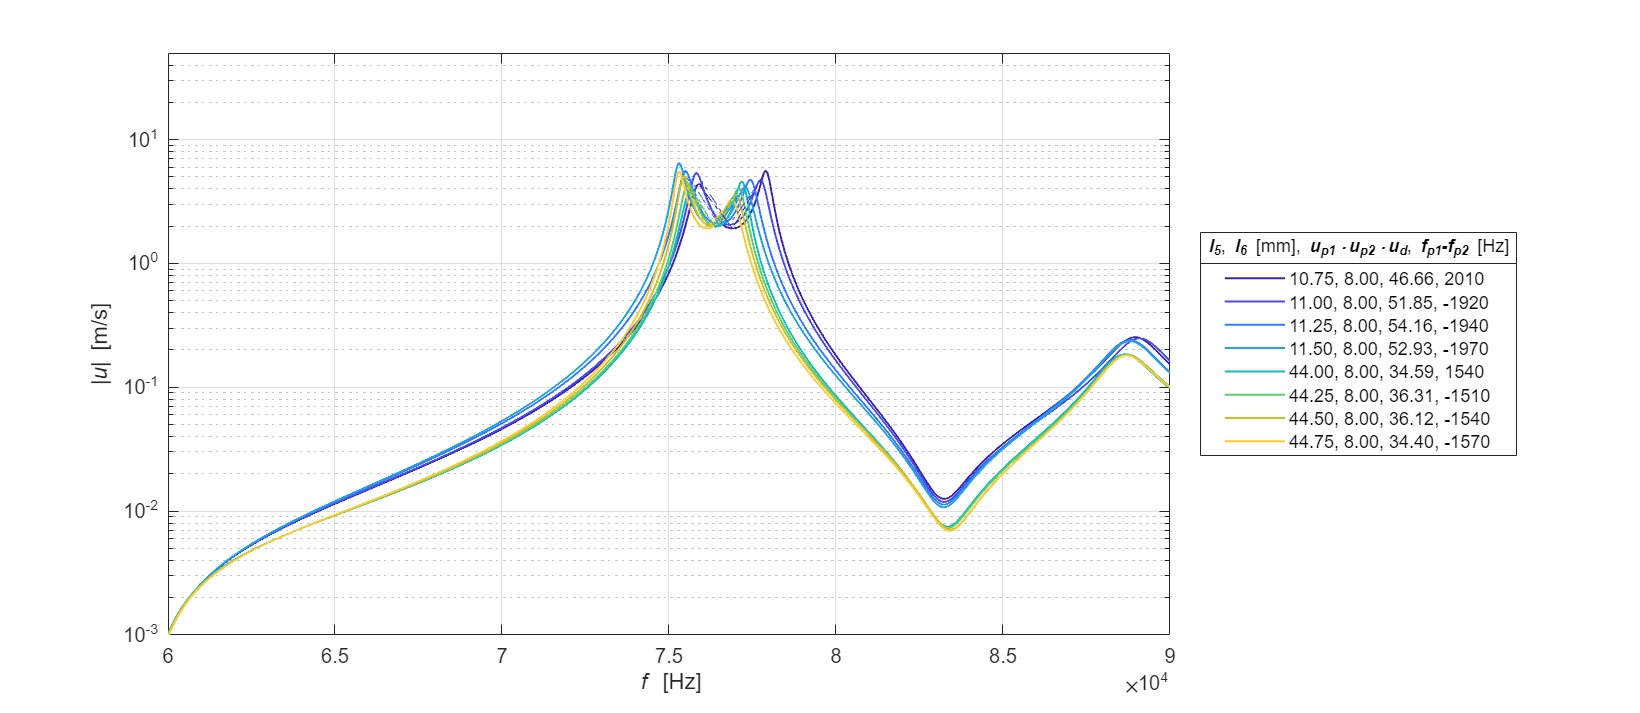

uSteppedPlateHighPowerTransducer.figure = figure('Name','f vs. u','Units','inches','Position',[0 0 11.5 5]);
uSteppedPlateHighPowerTransducer.axes = axes('Parent', uSteppedPlateHighPowerTransducer.figure);
hold(uSteppedPlateHighPowerTransducer.axes,'on');
C = colororder(parula(Study.nXdcr+1));
colororder(repmat(C(1:Study.nXdcr,:),3,1));

uSteppedPlateHighPowerTransducer.p = semilogy(Study.freqSolid, abs(Xdcr.uSteppedPlateHighPowerTransducer));

% for iXdcr = 4:4
for iXdcr = 1:Study.nXdcr
    tempI = [Xdcr.iPeak(iXdcr,1) Xdcr.iDip(iXdcr) Xdcr.iPeak(iXdcr,2)];
    plot(Study.freqSolid(tempI), abs(Xdcr.uSteppedPlateHighPowerTransducer(tempI,iXdcr)), ...
        'HandleVisibility','off','LineStyle','-.')
    set(uSteppedPlateHighPowerTransducer.p(iXdcr), 'LineWidth', 1,'DisplayName', ...
        [num2str(Xdcr.l5(iXdcr)*1e3,'%2.2f') ', ' ...
        num2str(Xdcr.l6(iXdcr)*1e3,'%2.2f') ', ' ...
        num2str(prod(abs(Xdcr.uSteppedPlateHighPowerTransducer(tempI,iXdcr))),'%2.2f') ', ' ...
        num2str(diff(Study.freqSolid(Xdcr.iPeak(iXdcr,:)))*-1,'%d')]);
end

box(uSteppedPlateHighPowerTransducer.axes,'on');
grid(uSteppedPlateHighPowerTransducer.axes,'on');
hold(uSteppedPlateHighPowerTransducer.axes,'off');
xlabel('{\itf} [Hz]')
ylabel('|{\itu}| [m/s]')
ylim(uSteppedPlateHighPowerTransducer.axes,[1e-3 5e1]);
set(uSteppedPlateHighPowerTransducer.axes,'XScale','linear','YScale','log');
uSteppedPlateHighPowerTransducer.lgd = legend(uSteppedPlateHighPowerTransducer.axes,'Location','eastoutside','Orientation','vertical');
title(uSteppedPlateHighPowerTransducer.lgd, ...
    '{\itl}_{5}{\rm,} {\itl}_{6} {\rm[mm],} {\itu}_{p1}\cdot{\itu}_{p2}\cdot{\itu}_d{\rm,} {\itf}_{p1}-{\itf}_{p2} {\rm[Hz]}')
savefig(uSteppedPlateHighPowerTransducer.figure,'r_o=7, e=7.fig')
saveas(uSteppedPlateHighPowerTransducer.figure,'r_o=7, e=7.svg')

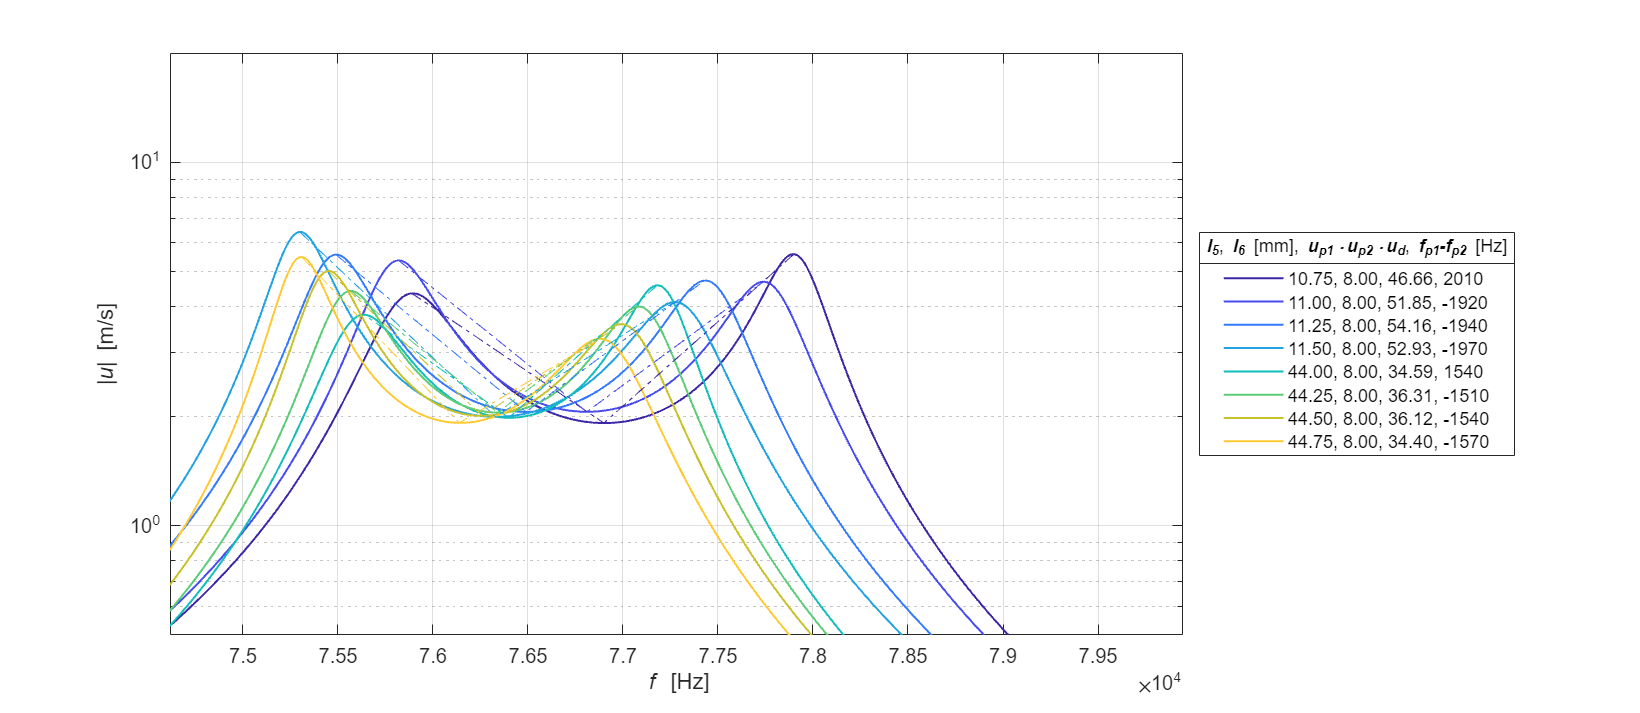

uSteppedPlateHighPowerTransducer.figureMag = figure('Name','f vs. u','Units','inches','Position',[0 0 11.5 5]);
uSteppedPlateHighPowerTransducer.axesMag = axes('Parent', uSteppedPlateHighPowerTransducer.figureMag);
hold(uSteppedPlateHighPowerTransducer.axesMag,'on');
C = colororder(parula(Study.nXdcr+1));
colororder(repmat(C(1:Study.nXdcr,:),3,1));

uSteppedPlateHighPowerTransducer.p = semilogy(Study.freqSolid, abs(Xdcr.uSteppedPlateHighPowerTransducer));

% for iXdcr = 4:4
for iXdcr = 1:Study.nXdcr
    tempI = [Xdcr.iPeak(iXdcr,1) Xdcr.iDip(iXdcr) Xdcr.iPeak(iXdcr,2)];
    plot(Study.freqSolid(tempI), abs(Xdcr.uSteppedPlateHighPowerTransducer(tempI,iXdcr)), ...
        'HandleVisibility','off','LineStyle','-.')
    set(uSteppedPlateHighPowerTransducer.p(iXdcr), 'LineWidth', 1,'DisplayName', ...
        [num2str(Xdcr.l5(iXdcr)*1e3,'%2.2f') ', ' ...
        num2str(Xdcr.l6(iXdcr)*1e3,'%2.2f') ', ' ...
        num2str(prod(abs(Xdcr.uSteppedPlateHighPowerTransducer(tempI,iXdcr))),'%2.2f') ', ' ...
        num2str(diff(Study.freqSolid(Xdcr.iPeak(iXdcr,:)))*-1,'%d')]);
end

box(uSteppedPlateHighPowerTransducer.axesMag,'on');
grid(uSteppedPlateHighPowerTransducer.axesMag,'on');
hold(uSteppedPlateHighPowerTransducer.axesMag,'off');
xlabel('{\itf} [Hz]')
ylabel('|{\itu}| [m/s]')
xlim(uSteppedPlateHighPowerTransducer.axesMag,[Plate.FREQ*0.98 Plate.FREQ*1.05]);
ylim(uSteppedPlateHighPowerTransducer.axesMag,[5e-1 2e1]);
set(uSteppedPlateHighPowerTransducer.axesMag,'XScale','linear','YScale','log');
uSteppedPlateHighPowerTransducer.lgdMag = legend(uSteppedPlateHighPowerTransducer.axesMag,'Location','eastoutside','Orientation','vertical');
title(uSteppedPlateHighPowerTransducer.lgdMag, ...
    '{\itl}_{5}{\rm,} {\itl}_{6} {\rm[mm],} {\itu}_{p1}\cdot{\itu}_{p2}\cdot{\itu}_d{\rm,} {\itf}_{p1}-{\itf}_{p2} {\rm[Hz]}')
savefig(uSteppedPlateHighPowerTransducer.figureMag,'r_o=7, e=7_mag.fig')
saveas(uSteppedPlateHighPowerTransducer.figureMag,'r_o=7, e=7_mag.svg')